4.7    （示教M文件fzerotx）实时脚本

由张志涌编写、修改于 2023.1。

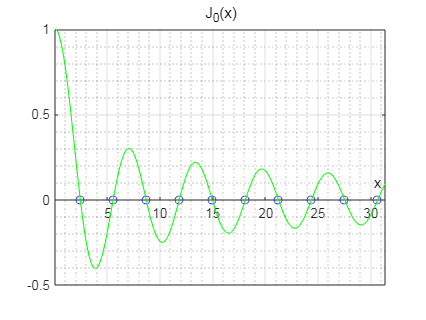

clear,clf
J0 = @(x) besselj(0,x);
z=zeros(1,10);
for n = 1:10
   z(n) = fzerotx(J0,[(n-1) n]*pi);
end
x = 0:pi/50:10*pi;
y = J0(x);
h=plot(z,zeros(1,10),'bo',x,y,'g-');
axis([0 10*pi -0.5 1.0])
set(gca,'XAxisLocation','origin')
grid on,grid minor
xlabel('x')
title('J_{0}(x)')

F=@(x,y) besselj(0,x)-y;
xi = fzerotx(F,[0,2],.5)

xi =    1.521144057668765


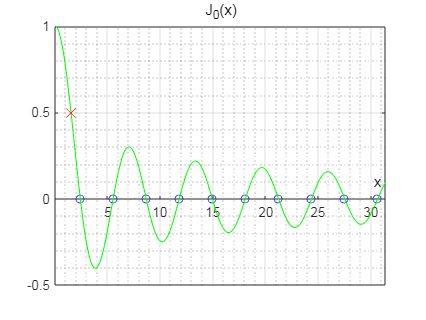

line(xi,0.5,'Color','r','Marker','x','Markersize',10)